# 繪圖軟體應用 第8周(10/30)

## 1)上周複習

clear;clc;clf
[x,y,z] = peaks

x =    -3.0000   -2.8750   -2.7500   -2.6250   -2.5000   -2.3750   -2.2500   -2.1250   -2.0000   -1.8750   -1.7500   -1.6250   -1.5000   -1.3750   -1.2500   -1.1250   -1.0000   -0.8750   -0.7500   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750    2.0000    2.1250    2.2500    2.3750    2.5000    2.6250    2.7500    2.8750    3.0000
   -3.0000   -2.8750   -2.7500   -2.6250   -2.5000   -2.3750   -2.2500   -2.1250   -2.0000   -1.8750   -1.7500   -1.6250   -1.5000   -1.3750   -1.2500   -1.1250   -1.0000   -0.8750   -0.7500   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750    2.0000    2.1250    2.2500    2.3750    2.5000    2.6250    2.7500    2.8750    3.0000
   -3.0000   -

y =    -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000
   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750
   -2.7500   -

z =     0.0001    0.0001    0.0002    0.0004    0.0007    0.0011    0.0017    0.0025    0.0034    0.0043    0.0051    0.0052    0.0042    0.0010   -0.0050   -0.0151   -0.0299   -0.0500   -0.0752   -0.1049   -0.1373   -0.1703   -0.2010   -0.2268   -0.2450   -0.2539   -0.2527   -0.2419   -0.2228   -0.1976   -0.1687   -0.1388   -0.1100   -0.0839   -0.0617   -0.0437   -0.0298   -0.0195   -0.0123   -0.0074   -0.0043   -0.0024   -0.0013   -0.0006   -0.0003   -0.0001   -0.0001   -0.0000   -0.0000
    0.0001    0.0002    0.0004    0.0006    0.0010    0.0017    0.0026    0.0037    0.0051    0.0064    0.0073    0.0070    0.0046   -0.0013   -0.0123   -0.0299   -0.0555   -0.0898   -0.1327   -0.1828   -0.2373   -0.2924   -0.3437   -0.3862   -0.4161   -0.4302   -0.4276   -0.4087   -0.3761   -0.3332   -0.2843   -0.2337   -0.1851   -0.1412   -0.1038   -0.0735   -0.0501   -0.0328   -0.0207   -0.0125   -0.0073   -0.0040   -0.0021   -0.0011   -0.0005   -0.0002   -0.0001   -0.0000   -0.0000
    0.0002    

figure(1)
pcolor(x,y,z)
shading interp  % 做線性內插 (減少色階差異)
colorbar('v')
m = colormap('jet') %三個column代表RGB

m =          0    0.5000    1.0000
         0    1.0000    1.0000
    0.5000    1.0000    0.5000
    1.0000    1.0000         0
    1.0000    0.5000         0


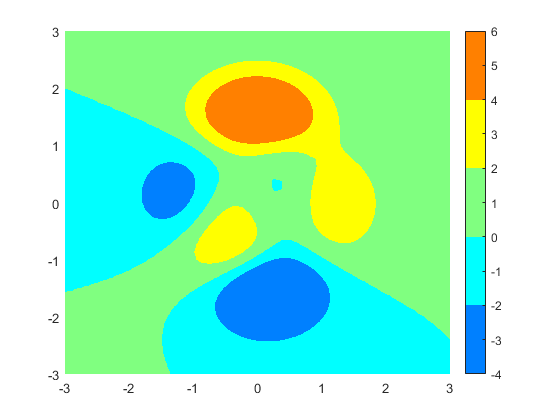

caxis([-4 6])

自己調配colormap

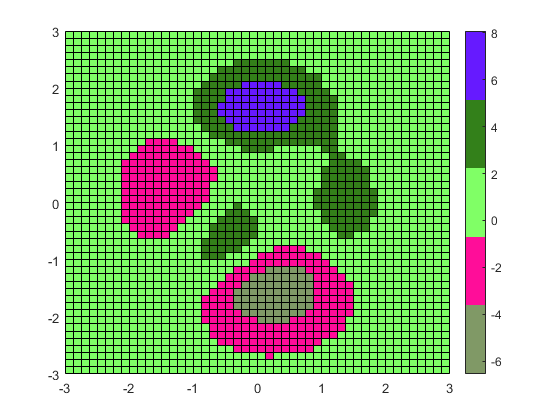

figure(2)
pcolor(x,y,z)
% shading interp  % 做線性內插 (減少色階差異)
colorbar('v')
load tryc.txt %載入自己的資料變數，值為0到1之間的5*3陣列
colormap(tryc)

## 2) 等值線圖

clear;clc;clf
[x2,y2,z2] = peaks

x2 =    -3.0000   -2.8750   -2.7500   -2.6250   -2.5000   -2.3750   -2.2500   -2.1250   -2.0000   -1.8750   -1.7500   -1.6250   -1.5000   -1.3750   -1.2500   -1.1250   -1.0000   -0.8750   -0.7500   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750    2.0000    2.1250    2.2500    2.3750    2.5000    2.6250    2.7500    2.8750    3.0000
   -3.0000   -2.8750   -2.7500   -2.6250   -2.5000   -2.3750   -2.2500   -2.1250   -2.0000   -1.8750   -1.7500   -1.6250   -1.5000   -1.3750   -1.2500   -1.1250   -1.0000   -0.8750   -0.7500   -0.6250   -0.5000   -0.3750   -0.2500   -0.1250         0    0.1250    0.2500    0.3750    0.5000    0.6250    0.7500    0.8750    1.0000    1.1250    1.2500    1.3750    1.5000    1.6250    1.7500    1.8750    2.0000    2.1250    2.2500    2.3750    2.5000    2.6250    2.7500    2.8750    3.0000
   -3.0000   

y2 =    -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000   -3.0000
   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750   -2.8750
   -2.7500   

z2 =     0.0001    0.0001    0.0002    0.0004    0.0007    0.0011    0.0017    0.0025    0.0034    0.0043    0.0051    0.0052    0.0042    0.0010   -0.0050   -0.0151   -0.0299   -0.0500   -0.0752   -0.1049   -0.1373   -0.1703   -0.2010   -0.2268   -0.2450   -0.2539   -0.2527   -0.2419   -0.2228   -0.1976   -0.1687   -0.1388   -0.1100   -0.0839   -0.0617   -0.0437   -0.0298   -0.0195   -0.0123   -0.0074   -0.0043   -0.0024   -0.0013   -0.0006   -0.0003   -0.0001   -0.0001   -0.0000   -0.0000
    0.0001    0.0002    0.0004    0.0006    0.0010    0.0017    0.0026    0.0037    0.0051    0.0064    0.0073    0.0070    0.0046   -0.0013   -0.0123   -0.0299   -0.0555   -0.0898   -0.1327   -0.1828   -0.2373   -0.2924   -0.3437   -0.3862   -0.4161   -0.4302   -0.4276   -0.4087   -0.3761   -0.3332   -0.2843   -0.2337   -0.1851   -0.1412   -0.1038   -0.0735   -0.0501   -0.0328   -0.0207   -0.0125   -0.0073   -0.0040   -0.0021   -0.0011   -0.0005   -0.0002   -0.0001   -0.0000   -0.0000
    0.0002   

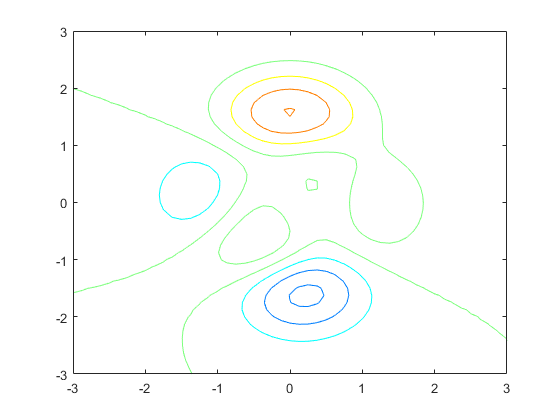

figure(1)
contour(x2,y2,z2)
colormap('jet')

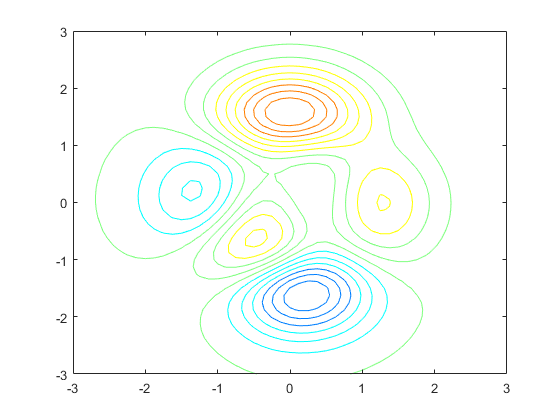

contour(x2,y2,z2,15) %contour(z,n) 畫n條等值線

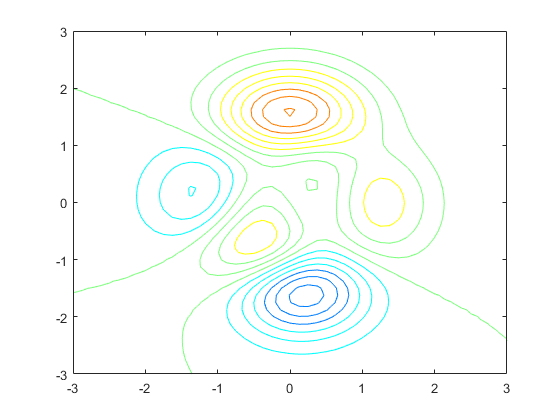

contour(x2,y2,z2,[-6:1:8])% contour(x,y,z,v) 指定等值線的向量

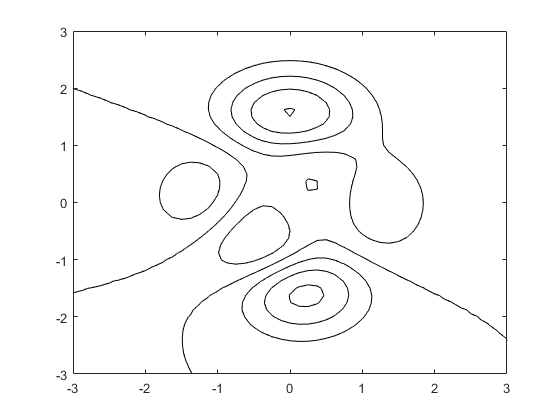

                       % 指定從 -6 畫到 8 (間隔值1)
contour(x2,y2,z2,'k') %等值線特性

標示等值線的值

figure(2)
[c1,h1] = contour(x2,y2,z2)

c1 =    -6.0000    0.4022    0.3750    0.2500    0.1250    0.0109         0   -0.0117         0    0.0846    0.1250    0.2500    0.3750    0.4299    0.4694    0.4022   -4.0000    0.2564    0.2500    0.1250    0.0966         0   -0.1250   -0.2215   -0.2500   -0.3224   -0.3545   -0.3324   -0.2599   -0.2500   -0.1313   -0.1250         0    0.0777    0.1250    0.2500    0.3750    0.5000    0.5992    0.6250    0.7340    0.7500    0.7963    0.8127    0.7881    0.7500    0.7186    0.6250    0.5866    0.5000
   15.0000   -1.7500   -1.7717   -1.8204   -1.8153   -1.7500   -1.7110   -1.6250   -1.6053   -1.5000   -1.4750   -1.4395   -1.4603   -1.5000   -1.6250   -1.7500   35.0000   -2.1250   -2.1262   -2.1293   -2.1250   -2.1097   -2.0628   -2.0000   -1.9729   -1.8750   -1.7500   -1.6250   -1.5000   -1.4901   -1.3750   -1.3704   -1.2903   -1.2500   -1.2281   -1.1911   -1.1803   -1.2029   -1.2500   -1.2671   -1.3750   -1.4042   -1.5000   -1.6250   -1.7500   -1.8234   -1.8750   -1.9709   -2.0000   -

h1 =   Contour with properties:

    LineColor: 'flat'
    LineStyle: '-'
    LineWidth: 0.5000
         Fill: 'off'
    LevelList: [-6 -4 -2 0 2 4 6 8]
        XData: [49×49 double]
        YData: [49×49 double]
        ZData: [49×49 double]

  Show all properties


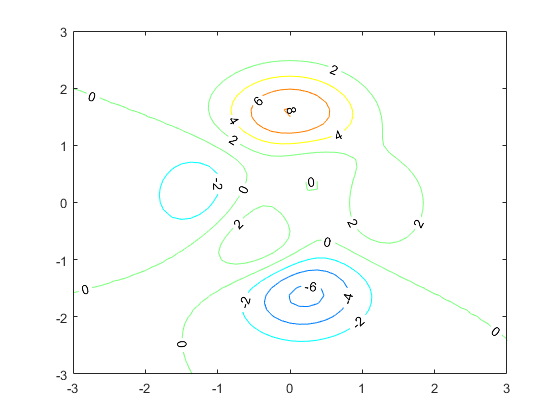

clabel(c1,h1)

pcolor()

figure(3)
pcolor(x2,y2,z2)
shading interp
hold on 
[c2,h2]=contour(x2,y2,z2,[-6:1:8],'k')

c2 =    -6.0000    0.4022    0.3750    0.2500    0.1250    0.0109         0   -0.0117         0    0.0846    0.1250    0.2500    0.3750    0.4299    0.4694    0.4022   -5.0000    0.5191    0.5000    0.3750    0.2500    0.1250         0   -0.1250   -0.1335   -0.1978   -0.1893   -0.1250   -0.1182         0    0.0376    0.1250    0.2500    0.3750    0.5000    0.5522    0.6250    0.6424    0.6594    0.6250    0.6240    0.5191   -4.0000    0.2564    0.2500    0.1250    0.0966         0   -0.1250   -0.2215
   15.0000   -1.7500   -1.7717   -1.8204   -1.8153   -1.7500   -1.7110   -1.6250   -1.6053   -1.5000   -1.4750   -1.4395   -1.4603   -1.5000   -1.6250   -1.7500   25.0000   -1.8750   -1.8900   -1.9564   -1.9893   -1.9912   -1.9593   -1.8831   -1.8750   -1.7500   -1.6250   -1.5106   -1.5000   -1.3997   -1.3750   -1.3326   -1.2973   -1.2959   -1.3385   -1.3750   -1.4696   -1.5000   -1.6250   -1.7472   -1.7500   -1.8750   35.0000   -2.1250   -2.1262   -2.1293   -2.1250   -2.1097   -2.0628   -

h2 =   Contour with properties:

    LineColor: [0 0 0]
    LineStyle: '-'
    LineWidth: 0.5000
         Fill: 'off'
    LevelList: [-6 -5 -4 -3 -2 -1 0 1 2 3 4 5 6 7 8]
        XData: [49×49 double]
        YData: [49×49 double]
        ZData: [49×49 double]

  Show all properties


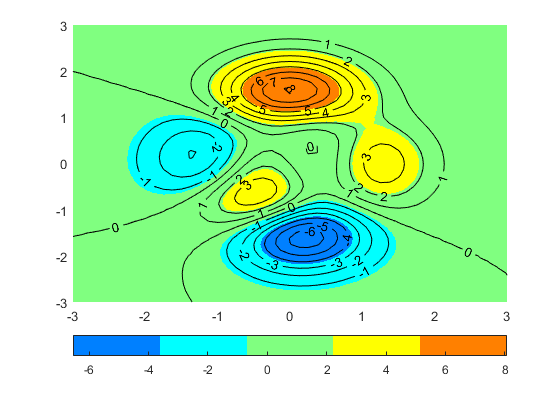

clabel(c2,h2)
hold off
colorbar('h')
colormap('jet')

## 3) meshgrid( )

clear;clc;clf
figure(1)
vx = 2:4

vx =      2     3     4


vy = 0:3

vy =      0     1     2     3


[xx,yy] = meshgrid(vx,vy)

xx =      2     3     4
     2     3     4
     2     3     4
     2     3     4


yy =      0     0     0
     1     1     1
     2     2     2
     3     3     3


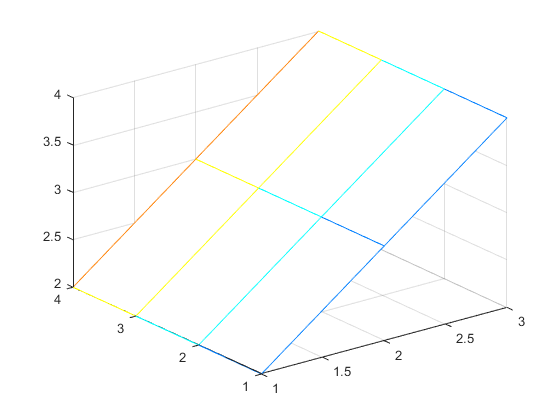

mesh(xx,yy)

surf

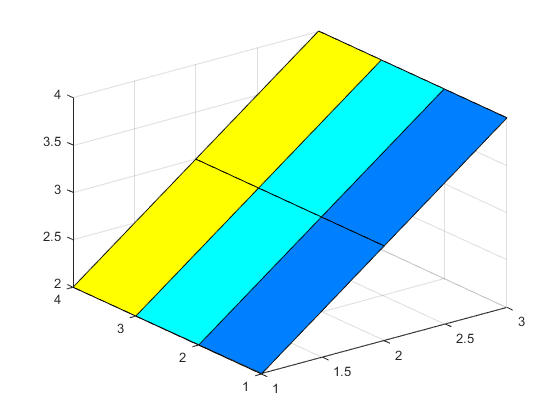

figure(2)
surf(xx,yy)

plot3()

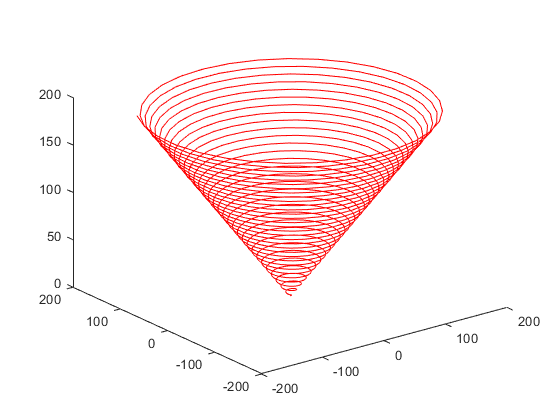

figure(3)
t = linspace(1,200,1000);
plot3(t.*sin(t),t.*cos(t),t,'r')

contourf() : 塗顏色填滿(fill)等高線的contour

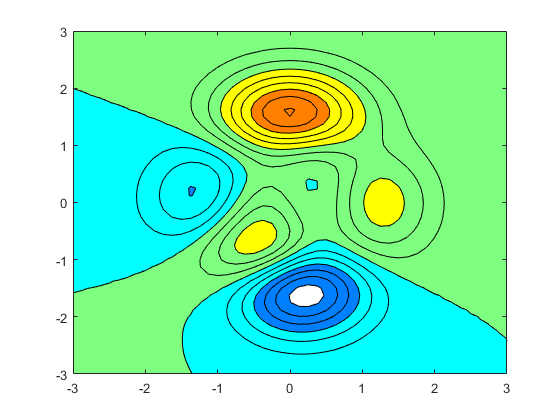

clear;clc;clf
[x,y,z] = peaks;
[c,h] = contourf(x,y,z,[-6:1:8],'k');

% clabel(c,h)

## 4) 三維繪圖視角

view

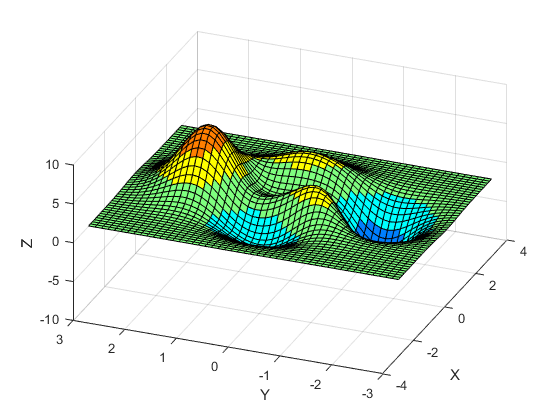

caz = -68.1986

cel = 42.8760

clear;clc;clf
[X,Y,Z] = peaks;
surf(X,Y,Z)
xlabel('X')
ylabel('Y')
zlabel('Z')
v = [-5 -2 5];
[caz,cel] = view(v)